# Exam July 16 / 2016

clear
syms q0 q1 V0 V1 t T a b c tau dq

% Declare equation system for joint space trajectory

eq(1) = a+b+c == 1;
eq(2) = c == V0*T/dq;
eq(3) = 3*a+2*b+c == V1*T/dq;
eq.';
[as,bs,cs]=solve(eq.',[a b c])

$$as = \frac{T\,V_{0}}{\mathrm{dq}}+\frac{T\,V_{1}}{\mathrm{dq}}-2$$

$$bs = 3-\frac{T\,V_{1}}{\mathrm{dq}}-\frac{2\,T\,V_{0}}{\mathrm{dq}}$$

$$cs = \frac{T\,V_{0}}{\mathrm{dq}}$$


q_des = q0 + dq*(as*tau^3 + bs*tau^2 + cs*tau) % q desired

$$q\_des = q_{0}+\mathrm{dq}\,\left(\tau^{3}\,\left(\frac{T\,V_{0}}{\mathrm{dq}}+\frac{T\,V_{1}}{\mathrm{dq}}-2\right)-\tau^{2}\,\left(\frac{2\,T\,V_{0}}{\mathrm{dq}}+\frac{T\,V_{1}}{\mathrm{dq}}-3\right)+\frac{T\,V_{0}\,\tau }{\mathrm{dq}}\right)$$

q_des_0 = subs(q_des,V0,0)

$$q\_des\_0 = q_{0}-\mathrm{dq}\,\left(\tau^{2}\,\left(\frac{T\,V_{1}}{\mathrm{dq}}-3\right)-\tau^{3}\,\left(\frac{T\,V_{1}}{\mathrm{dq}}-2\right)\right)$$

q_des_1 = subs(q_des,[V0 dq tau],[0 q1-q0 t/T]) %

$$q\_des\_1 = q_{0}-\left(q_{0}-q_{1}\right)\,\left(\frac{t^{2}\,\left(\frac{T\,V_{1}}{q_{0}-q_{1}}+3\right)}{T^{2}}-\frac{t^{3}\,\left(\frac{T\,V_{1}}{q_{0}-q_{1}}+2\right)}{T^{3}}\right)$$


% w is omega, for angular velocity
% acc is angular acceleration
w = diff(q_des_1,t)

$$w = \left(\frac{3\,t^{2}\,\left(\frac{T\,V_{1}}{q_{0}-q_{1}}+2\right)}{T^{3}}-\frac{2\,t\,\left(\frac{T\,V_{1}}{q_{0}-q_{1}}+3\right)}{T^{2}}\right)\,\left(q_{0}-q_{1}\right)$$

acc = diff(w,t)

$$acc = -\left(q_{0}-q_{1}\right)\,\left(\frac{2\,\left(\frac{T\,V_{1}}{q_{0}-q_{1}}+3\right)}{T^{2}}-\frac{6\,t\,\left(\frac{T\,V_{1}}{q_{0}-q_{1}}+2\right)}{T^{3}}\right)$$


w0 = subs(w,t,0) % angular velocity at initial time

$$w0 = 0$$

wT = subs(w,t,T) % angular velocity at end time

$$wT = \left(\frac{3\,\left(\frac{T\,V_{1}}{q_{0}-q_{1}}+2\right)}{T}-\frac{2\,\left(\frac{T\,V_{1}}{q_{0}-q_{1}}+3\right)}{T}\right)\,\left(q_{0}-q_{1}\right)$$


acc0 = subs(acc,t,0) % angular acceleration at initial time

$$acc0 = -\frac{2\,\left(\frac{T\,V_{1}}{q_{0}-q_{1}}+3\right)\,\left(q_{0}-q_{1}\right)}{T^{2}}$$

% to find the moment where Max speed happens, 
% set acc = 0, and solve for t

%replace the given values
qdeval = subs(q_des_1,[q0 q1 V1],[15 45 30])

$$qdeval = \frac{30\,t^{3}\,\left(T-2\right)}{T^{3}}-\frac{30\,t^{2}\,\left(T-3\right)}{T^{2}}+15$$

weval = diff(qdeval,t)

$$weval = \frac{90\,t^{2}\,\left(T-2\right)}{T^{3}}-\frac{60\,t\,\left(T-3\right)}{T^{2}}$$

acceval = diff(weval,t)

$$acceval = \frac{180\,t\,\left(T-2\right)}{T^{3}}-\frac{60\,\left(T-3\right)}{T^{2}}$$


t_vmax = solve(acceval == 0,t)

$$t\_vmax = \frac{T\,\left(T-3\right)}{3\,\left(T-2\right)}$$


%Get the value of max velocity.
wmax = subs(weval,t,t_vmax)

$$wmax = -\frac{10\,{\left(T-3\right)}^{2}}{T\,\left(T-2\right)}$$


%Solve for T, which in this case will be the time needed to reach that
%speed
Twmax = solve(wmax == 90,T)

$$Twmax = \left(\begin{array}{c} \frac{6}{5}-\frac{3\,\sqrt{6}}{10}\\ \frac{3\,\sqrt{6}}{10}+\frac{6}{5} \end{array}\right)$$



%Since the need the MINIMUM feasible motion time, the answer is
Twmax = eval(min(Twmax))

Twmax = 0.4652


t_vmax = eval(subs(t_vmax,T,Twmax))

t_vmax = 0.2561

wTvmax = subs(weval,T,t_vmax)

$$wTvmax = \frac{13356835426964820334577092814438400\,t}{5319884060150721093735036899761}-\frac{114693943475292782778650687957353163217047943905280\,t^{2}}{12270245477844477258300706650246224690034163991}$$

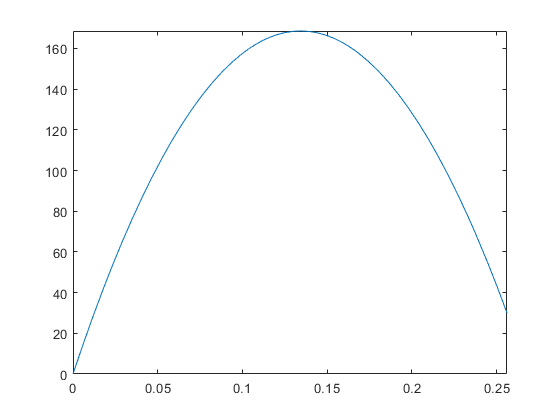

fplot(wTvmax,[0 t_vmax])

### Exercise 2

q = sym('q',[1 3])

$$q = \left(\begin{array}{ccc} q_{1} & q_{2} & q_{3} \end{array}\right)$$

dh= [pi/2 0 10 q(1);
       pi/2 0 0 q(2)
       0 0 0 q(3)];
   
T = getTranslationMatrix(dh,'alpha')

$$T = \left(\begin{array}{cccc} \sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right) & \cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ \cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & -\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{2}\right) & 10\\ 0 & 0 & 0 & 1 \end{array}\right)$$


[Jp Jo] = getJacobian(dh,'RRR','alpha')

$$Jp = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$Jo = \left(\begin{array}{ccc} 0 & \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & -\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 1 & 0 & -\cos\left(q_{2}\right) \end{array}\right)$$